# 

## MATLAB Fundamentals: Tutorial 02, Exercise 06

### August 2023

# 6.  Moving Robot  

In this final exercise, you apply most of what you have learned so far to the problem of a moving robot, like the line-tracking robot considered in the scope of this lab course. Figure 6-1 shows the geometry of the robot. It has two wheels driven by one motor each, and a third, ball-shaped support. 

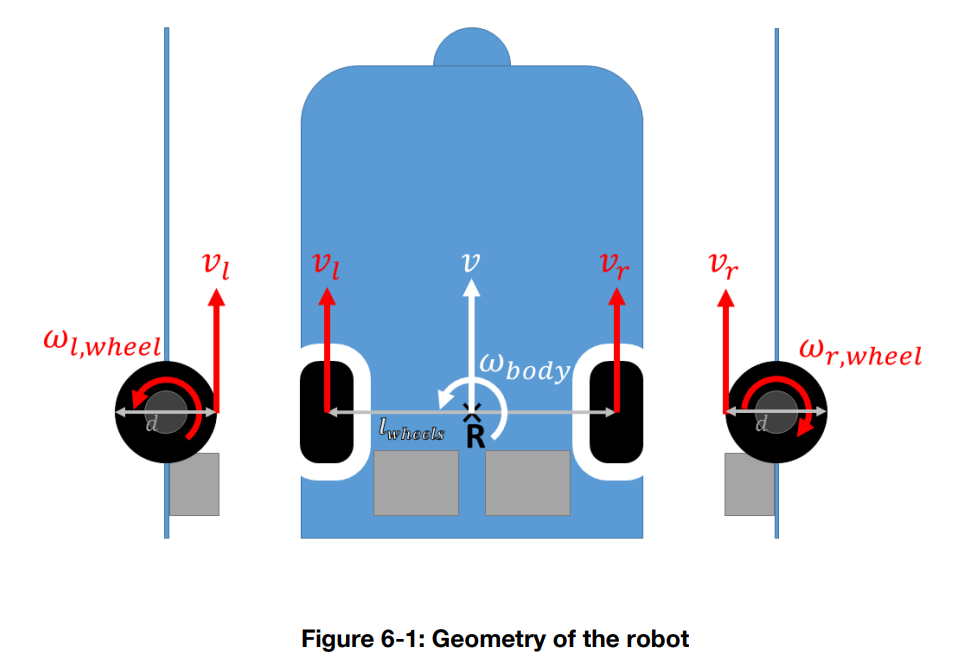

Consider the left and right wheel rotation rates $\omega_{lw}(t)$ and $\omega_{rw}(t)$ given. Using the wheels diameter 𝑑, the linear wheel speed can be calculated:


$$\begin{array}{rcl}
v_r &=& \omega_{rw} \frac d2 \\
v_l &=& \omega_{lw} \frac d2 \\
\end{array}$$


The forward speed at the reference point can then be calculated as:


$$v = \frac 12 \left( v_r + v_l \right)$$


and the rotational rate of the robot is:


$$\omega = \frac {1} {l_\text{wheels}} (v_r - v_l)$$


Using these quantities, the nonlinear equations of motion of the robot can be stated as:


$$\begin{array}{rcl}
\dot \phi &=& \omega \\
\dot x&=& v\cos\phi \\
\dot y&=& v\sin\phi
\end{array}$$


**Exercise**

(1)     Convert the systems of equations in MATLAB symbolic language. Let $t$ be positive.

(2)    Consider $\omega_{lw} = 8\sin^2t$ and $\omega_{rw} = 8\cos^2t$. What are the resulting robot speed $v^*$ and robot rotational rate $\omega^*$? (The star denotes this particular solution.) 

(3)    When is the first moment $t > 0$ at which the robot does not rotate (i.e. $\omega^* = 0$)? Assume $d = 0.03\text m$ and $l_{wheels} = 0.1\text m$. Give a 3-digit approximation. What happens if you do not specify the interval in which you are looking for the solution? What can you deduce regarding this function's behavior with assumptions?

### *Hint:* Make a first guess based on a symbolic plot, then determine the result by numeric equation solving, using `vpasolve`.

(4)    Determine the robot’s position after 50 seconds, $x(50\text s)$ and $y(50\text s)$.

### *Hint: *Make the right choice between definite and indefinite integration.

Technische Universität München – Lehrstuhl für Flugsystemdynamik – MATLAB Fundamentals: Tutorial 02 – August 2023